## Minimum time

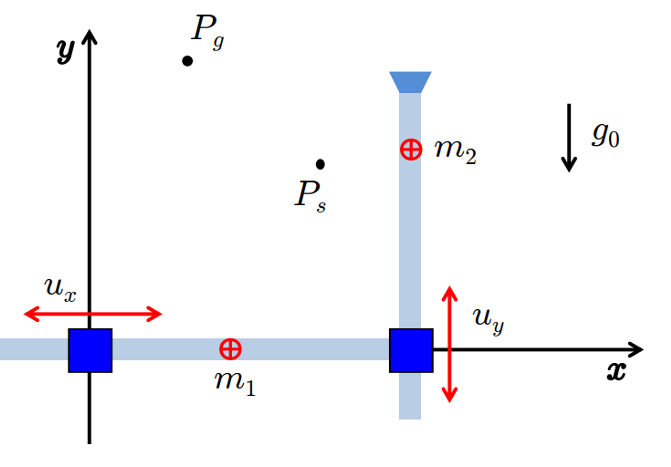

syms q1 q2 dq1 dq2 m1 m2 l1 l2 d1 d2 g0 I2 positive
syms ddq1 ddq2 positive

% Inertia Matrix
T1 = 0.5*m1*dq1^2

$$T1 = \frac{{{\mathrm{dq}}_{1}}^{2}\,m_{1}}{2}$$


x2 = q1

$$x2 = q_{1}$$

y2 = q2

$$y2 = q_{2}$$

vx2 = diff(x2, q1)*dq1 + diff(x2, q2)*dq2;
vy2 = diff(y2, q1)*dq1 + diff(y2, q2)*dq2;

T2 = 0.5*m2*[vx2 vy2]*[vx2; vy2;];

T = T1+T2

$$T = \frac{{{\mathrm{dq}}_{1}}^{2}\,m_{1}}{2}+\frac{{{\mathrm{dq}}_{1}}^{2}\,m_{2}}{2}+\frac{{{\mathrm{dq}}_{2}}^{2}\,m_{2}}{2}$$


% Inertia Matrix
M11 = diff(diff(T, dq1), dq1);
M12 = diff(diff(T, dq1), dq2);

M21 = diff(diff(T, dq2), dq1);
M22 = diff(diff(T, dq2), dq2);

M = [M11, M12;
     M21, M22;];

M = simplify(M);

disp('The inertia matrix M(q) is:');

The inertia matrix M(q) is:


disp(M);

$$\left(\begin{array}{cc} m_{1}+m_{2} & 0\\ 0 & m_{2} \end{array}\right)$$


% Potential Energy and Gravity Terms
U1 = 0;
U2 = m2*g0*q2;
U = [U1+U2;];
g_q = simplify([diff(U,q1); diff(U,q2);], Steps=100)

$$g\_q = \left(\begin{array}{c} 0\\ g_{0}\,m_{2} \end{array}\right)$$


% Inizializza la matrice C(q, dq) (3x3) a zeri simbolici:
C = sym(zeros(2,2));

% using the Christoffel symbols for a 3-DOF system
q  = [q1; q2;];
dq = [dq1; dq2;];

% Inizializza la matrice C(q, dq) (3x3) a zeri simbolici:
C = sym(zeros(2,2));

% Formula dei coefficienti di Christoffel (Robotics):
%   C(i,j) = 1/2 * SUM_k [ dM(i,j)/dq_k + dM(i,k)/dq_j - dM(k,j)/dq_i ] * dq_k
% Poi il vettore c(q,dq) = C(q,dq) * dq
for i = 1:2
    for j = 1:2
        % Costruisco ogni elemento C(i,j):
        tmp = 0;
        for k = 1:2
            tmp = tmp + 0.5 * ( ...
                diff(M(i,j), q(k)) + ...
                diff(M(i,k), q(j)) - ...
                diff(M(k,j), q(i)) ) * dq(k);
        end
        C(i,j) = simplify(tmp);  % semplifico
    end
end

% Finalmente calcolo il vettore c(q, dq):
c_vec = simplify(C * dq);

disp('La matrice di Coriolis C(q,dq) è:');

La matrice di Coriolis C(q,dq) è:


disp(C);

$$\left(\begin{array}{cc} 0 & 0\\ 0 & 0 \end{array}\right)$$


disp('Il vettore c(q,dq) = C(q,dq)*dq è:');

Il vettore c(q,dq) = C(q,dq)*dq è:


disp(c_vec);

$$\left(\begin{array}{c} 0\\ 0 \end{array}\right)$$


disp('La matrice di Coriolis C(q,dq) è:');

La matrice di Coriolis C(q,dq) è:


disp(C);

$$\left(\begin{array}{cc} 0 & 0\\ 0 & 0 \end{array}\right)$$


disp('Il vettore c(q,dq) = C(q,dq)*dq è:');

Il vettore c(q,dq) = C(q,dq)*dq è:


disp(c_vec);

$$\left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

### Graphs and Utils

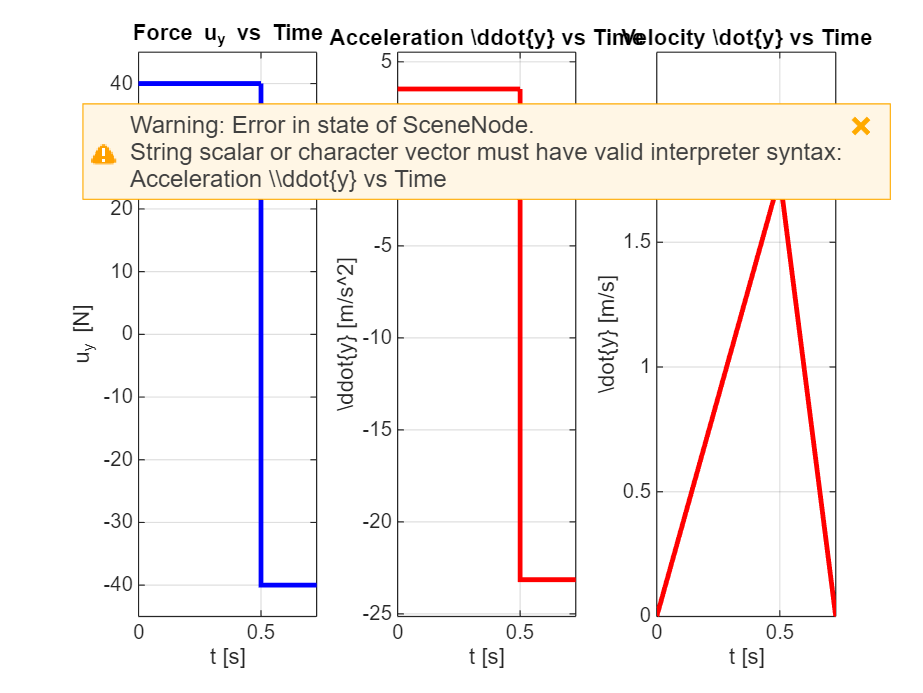

% Numerical values from the problem
Ps = [1, 0.3];         % Start position [m]
Pg = [0.6, 0.7];       % Goal position [m]
m1 = 5;                % Mass 1 [kg]
m2 = 3;                % Mass 2 [kg]
Ux_max = 40;           % Max force in x [N]
Uy_max = 40;           % Max force in y [N]
g0 = 9.81;             % Gravity [m/s^2]

% Compute displacement in y
Delta_y = Pg(2) - Ps(2);  % 0.7 - 0.3 = 0.4 m

% Compute acceleration bounds
a_y_max = Uy_max/m2 - g0;       % Max upward acceleration [m/s^2]
a_y_min = -Uy_max/m2 - g0;      % Max downward acceleration [m/s^2]

% Choose switch time (acceleration/deceleration duration)
Ty_switch = 0.5;    % You can experiment with other values

% Compute max velocity achieved
v_max = a_y_max * Ty_switch;

% Compute required total time Ty from displacement equation:
% Delta_y = a_y_max * Ty_switch * (Ty - Ty_switch)
Ty = Delta_y / (a_y_max * Ty_switch) + Ty_switch;

% --- Plot the 3 subfigures ---
figure;

% --- 1. Force profile u_y vs time ---
subplot(1,3,1);
stairs([0, Ty_switch, Ty_switch, Ty], [Uy_max, Uy_max, -Uy_max, -Uy_max], 'b', 'LineWidth', 2);
xlabel('t [s]'); ylabel('u_y [N]');
ylim([-Uy_max-5 Uy_max+5]);
xlim([0 Ty]);
title('Force u_y vs Time');
grid on;

% --- 2. Acceleration profile \ddot{y} vs time ---
subplot(1,3,2);
stairs([0, Ty_switch, Ty_switch, Ty], [a_y_max, a_y_max, a_y_min, a_y_min], 'r', 'LineWidth', 2);
xlabel('t [s]'); ylabel('\ddot{y} [m/s^2]');
ylim([a_y_min-2 a_y_max+2]);
xlim([0 Ty]);
title('Acceleration \ddot{y} vs Time');
grid on;

% --- 3. Velocity profile \dot{y} vs time ---
subplot(1,3,3);
% Triangular velocity profile
t_v = [0 Ty_switch Ty];            % Time points
v_y = [0 v_max 0];                 % Velocity values
plot(t_v(1:2), v_y(1:2), 'r', 'LineWidth', 2); hold on;
plot(t_v(2:3), v_y(2:3), 'r', 'LineWidth', 2);
xlabel('t [s]'); ylabel('\dot{y} [m/s]');
ylim([0 v_max+0.5]);
xlim([0 Ty]);
title('Velocity \dot{y} vs Time');
grid on;


% Display final timing values
fprintf('Computed total motion time Ty = %.3f s\n', Ty);

Computed total motion time Ty = 0.727 s


fprintf('Switch time Ty_switch = %.3f s\n', Ty_switch);

Switch time Ty_switch = 0.500 s


fprintf('Max velocity v_max = %.3f m/s\n', v_max);

Max velocity v_max = 1.762 m/s
